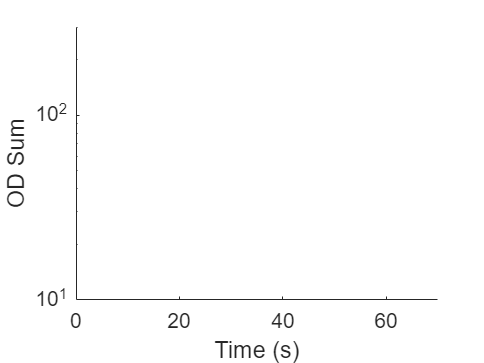

set(gca,'FontSize',16);
legend off;
%title('Left');
xlabel('Time (s)');
ylabel('OD Sum');
xlim([0 70])
ylim([10 300])
set(gca,'YScale','log')


close all
clear all
colors=npg(10); % Ten basic colors


% Input Area %

maindir=['\\Artemis-pc\e\Data\2023-09-04' ...
    '\'];%数据来源路径

plotnumber=0;%是否画原子数
plotradius=0;%是否画原子团半径
plotODsum=1;%是否画OD求和
plotSNRGain=0;%是否画SNR Gain
plotnoise_FR=0;%是否画Fringe removal后的noise OD
plotprecession=0;%是否画进动
plot2D=0;%二维形式比较数据，常用于二维扫描

first=201;%第一个文件夹序号
last=233;%最后一个文件夹序号

%设置横坐标公式为:xaxis=(first-1:last-1)*coeff+intercept;
intercept=0.0;%第一组数据的自变量`
coeff=0.5;%各组数据自变量间隔

% setXlabel='Ramsey Interrogation time ms';%横坐标label
% setXlabel='ROT pulse us';%横坐标label
% setXlabel='BusODT Hold s';%横坐标label
% setXlabel='MOT Hold s';%横坐标label
% setXlabel='Precession time ms';%横坐标label
% setXlabel='556 Freq V';%横坐标label
% setXlabel='399 Freq V';%横坐标label
% setXlabel='MOT Ramp s';%横坐标label
% setXlabel='Spin echo time s';%横坐标label
% setXlabel='Polar pulse us';%横坐标label
 setXlabel='Hold Time s';%横坐标label
% setXlabel='Ramp Time s';%横坐标label
% setXlabel='TOF s';%横坐标label
% setXlabel='Current V';%横坐标label
% setXlabel='power exponent';%横坐标label
% setXlabel='Shim V';%横坐标label
% setXlabel='MOT Freq (V)';%横坐标label


% read data %

datalength=last-first+1;
%xaxis=(0:last-first)*coeff+intercept;
xaxis=[0.1,0.5,1,2:2:60];

% Preallocation
numberofatoms1=zeros(datalength,1);
noise_OD=zeros(datalength,1);
countperpixel=zeros(datalength,1);

ODsum1=zeros(datalength,1);
ODsum2=zeros(datalength,1);
ODsum3=zeros(datalength,1);
ODsum4=zeros(datalength,1);
ODsum5=zeros(datalength,1);
ODsum6=zeros(datalength,1);


numberofatoms2=zeros(datalength,1);
radius=zeros(datalength,1);
noise_FR=zeros(datalength,1);
SNRGain=zeros(datalength,1);
Timelist=datetime(zeros(datalength,6));

tic
parfor i=1:datalength % parallel computing
    filestr=[maindir,'Abs-',num2str(i+first-1),'\Output.txt'];
    filestr;
    datafile=fopen(filestr);
    data_out=textscan(datafile,'%f');
    totaldata=data_out{1};
    fclose(datafile);

    filestr_time=[maindir,'Abs-',num2str(i+first-1),'\time.txt'];
    time_hd=fopen(filestr_time);
    data_time=textscan(time_hd,'%s %s');
    Timelist(i)=datetime([cell2mat(data_time{1,1}),' ',cell2mat(data_time{1,2})],'InputFormat','yyyy-MM-dd HH:mm:ss'); %转成时间序列
    fclose(time_hd);


    numberofatoms1(i)=totaldata(8);
    noise_OD(i)=totaldata(9);
    countperpixel(i)=totaldata(10);
    radius(i)=totaldata(11);
    ODsum1(i)=totaldata(12);
    noise_FR(i)=totaldata(13);
    SNRGain(i)=totaldata(14);



    filestr2=[maindir,'Abs-',num2str(i+first-1),'\ROI2.txt'];
    datafile2=fopen(filestr2);
    data_out2=textscan(datafile2,'%f');
    totaldata2=data_out2{1};
    fclose(datafile2);

    numberofatoms2(i)=totaldata2(3);
    ODsum2(i)=totaldata2(4);


end
toc

历时 0.505420 秒。


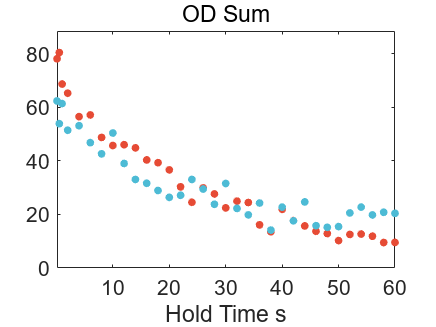

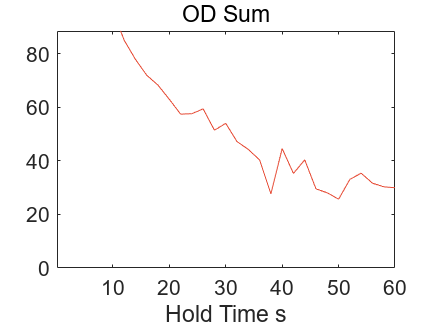

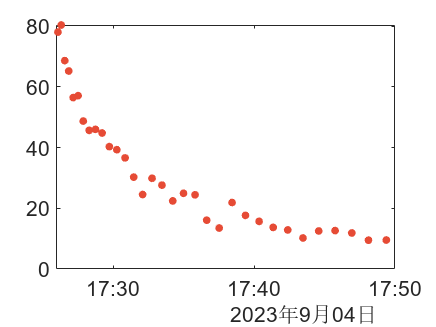

% plot number of atoms %

if plotnumber==1
    h1=figure('Name','Number of Atoms');
    %plot(xaxis,numberofatoms1,'.','Color',colors(3,:),'MarkerSize',20);
    plot(xaxis,numberofatoms2,'.','Color',colors(3,:),'MarkerSize',20);
    axis([min(xaxis) max(xaxis) min(numberofatoms1)*0.9 max(numberofatoms1)*1.1])
    title('Number of Atoms');
    xlabel(setXlabel);
    grid off
    set(gca,'FontSize',16)
    saveas(h1,[maindir,'Abs-',num2str(last),'\Numberofatoms.png'])
end


if plotODsum==1
    h2=figure('Name','OD Sum');
    plot(xaxis,ODsum1,'.','Color',colors(1,:),'MarkerSize',20);
    hold on
    plot(xaxis,ODsum2,'.','Color',colors(2,:),'MarkerSize',20);
    axis([min(xaxis) max(xaxis) 0 max(ODsum1)*1.1])
    title('OD Sum');
    xlabel(setXlabel);
    grid off
    set(gca,'FontSize',16)
    saveas(h2,[maindir,'Abs-',num2str(last),'\ODsum.png'])

    h2_0=figure('Name','OD Sum 1+2');
    ODsum12=ODsum1+ODsum2;
    plot(xaxis,ODsum12,'-','Color',colors(1,:),'MarkerSize',20);
    hold on
    axis([min(xaxis) max(xaxis) 0 max(ODsum1)*1.1])
    title('OD Sum');
    xlabel(setXlabel);
    grid off
    set(gca,'FontSize',16)
    saveas(h2_0,[maindir,'Abs-',num2str(last),'\ODsum12.png'])

    %% Plot time
    figure
    h3_0=plot(Timelist,ODsum1,'.','Color',colors(1,:),'MarkerSize',20);
    grid off
    set(gca,'FontSize',16)
    saveas(h3_0,[maindir,'Abs-',num2str(last),'\time.png'])

end

% plot radius %

if plotradius==1
    h3=figure('Name','Radius');
    plot(xaxis,radius,'.','Color',[0 98 132]./255.0,'MarkerSize',20);
    axis([min(xaxis) max(xaxis) min(radius)*0.9 max(radius)*1.1])
    title('Radius');
    xlabel(setXlabel);
    grid off
    set(gca,'FontSize',16)
end



% plot SNRGain %

if plotSNRGain==1
    h4=figure('Name','SNRGain');
    plot(xaxis,SNRGain,'.','Color',[0 98 132]./255.0,'MarkerSize',20);
    axis([min(xaxis) max(xaxis) min(SNRGain)*0.9 max(SNRGain)*1.1])
    title('SNR Gain');
    xlabel(setXlabel);
    grid off
    set(gca,'FontSize',16)
end



% plot noise_FR %

if plotnoise_FR==1
    h5=figure('Name','Noise_FR');
    plot(xaxis,noise_FR,'.','Color',[0 98 132]./255.0,'MarkerSize',20);
    axis([min(xaxis) max(xaxis) min(noise_FR)*0.9 max(noise_FR)*1.1])
    title('Noise FR');
    xlabel(setXlabel);
    grid off
    set(gca,'FontSize',16)
end


% plot precession %

if plotprecession==1
    %relativeOD=ODsum1;
    %relativeOD=ODsum2./ODsum1;
    relativeOD=(ODsum1-ODsum2)./(ODsum1+ODsum2);
    s1=ODsum1;
    s2=ODsum2;
    relativeOD2=(ODsum3-ODsum4)./(ODsum3+ODsum4);
    s3=ODsum3;
    s4=ODsum4;




    %     relativeOD=ODsum3./ODsum2;

    %     s1=(ODsum1+ODsum3+ODsum5)./3;
    %     s2=(ODsum2+ODsum4+ODsum6)./3;
    %     relativeOD=(s1-s2)./(s1+s2);



    h6=figure('Name','Precession');
    plot(xaxis,relativeOD,'.-','Color',colors(8,:),'MarkerSize',16);

    hold on;
    plot(xaxis,relativeOD2,'.-','Color',colors(2,:),'MarkerSize',16);
    legend('Yb-173','Yb-171');


    %axis([min(xaxis) max(xaxis) -1 1])
    axis([min(xaxis) max(xaxis) (min(relativeOD)-0.1) max(relativeOD)+0.1])
    %axis([min(xaxis) max(xaxis) min(relativeOD)*0.9 max(relativeOD)*1.1])
    title(' ');
    xlabel(setXlabel);
    %ylabel('OD_2/OD_1')
    %ylabel('OD_1')
    ylabel('S_z')
    grid off
    set(gca,'FontSize',16)
    saveas(h6,[maindir,'Abs-',num2str(last),'\precession.png'])


    %relativeOD_2=ODsum2./ODsum1;
    relativeOD_2=ODsum1./ODsum2;
    %relativeOD=(ODsum1-ODsum2)./(ODsum1+ODsum2);
    h7=figure('Name','ODsum2 versus OD sum1');
    plot(xaxis,relativeOD_2,'.','Color',colors(8,:),'MarkerSize',16);
    axis([min(xaxis) max(xaxis) 0.6 1.2])
    title(' ');
    xlabel(setXlabel);
    ylabel('S_z')
    grid off
    set(gca,'FontSize',16)
    saveas(h7,[maindir,'Abs-',num2str(last),'\population.png'])


end



% Plot 2D %

if plot2D==1
    first_para=[0.1,0.25:0.25:1.0];
    second_para=0.1:0.1:1.0;
    xlabel_2D='Overlap time (s)' ; % first_para
    ylabel_2D='Ramp-down time (s)'; % second_para

    data_2D=reshape(numberofatoms1,length(second_para),length(first_para));% 数据竖列重排

    fig2d=figure
    b = bar3(data_2D,1);
    colorbar
    for k = 1:length(b)
        zdata = b(k).ZData;
        b(k).CData = zdata;
        b(k).FaceColor = 'interp';
    end
    axis([])
    xlim([1-0.5,length(first_para)+0.5])
    ylim([1-0.5,length(second_para)+0.5])
    xticks([1:length(first_para)])
    yticks([1:length(second_para)])
    set(gca,'XTickLabel',first_para)
    set(gca,'YTickLabel',second_para)
    xlabel(xlabel_2D)
    ylabel(ylabel_2D)
    view([0 90])
    saveas(fig2d,[maindir,'Abs-',num2str(last),'\Compare2D.fig'])
    saveas(fig2d,[maindir,'Abs-',num2str(last),'\Compare2D.png'])
end



f_right = figure;
fit1=createFit(xaxis,ODsum1')

fit1 =      常规模型:
     fit1(x) = a*exp(-x/t1)+a2*exp(-x/t2)
     系数(置信边界为 95%):
       a =       66.42  (62.15, 70.7)
       a2 =       15.26  (8.461, 22.06)
       t1 =       30.29  (27.6, 32.97)
       t2 =       1.253  (-0.06554, 2.571)

fit2=createFit(xaxis,ODsum2')

fit2 =      常规模型:
     fit2(x) = a*exp(-x/t1)+a2*exp(-x/t2)
     系数(置信边界为 95%):
       a =       17.05  (-23.66, 57.76)
       a2 =       43.22  (4.175, 82.26)
       t1 =   3.144e+05  (-3.699e+09, 3.7e+09)
       t2 =       16.89  (-1.211, 34.98)

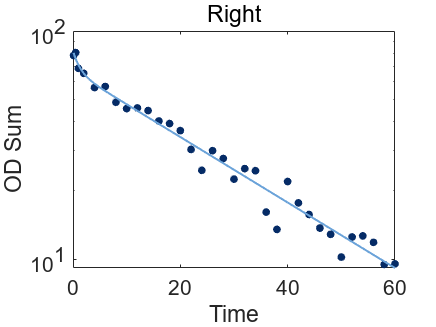

l1=plot(fit1,xaxis,ODsum1);

l1(1).Color=[0.02,0.17,0.40];
l1(2).Color=[0.42,0.64,0.85];
l1(1).MarkerSize=20;
l1(2).LineWidth=1.5;
set(gca,'Yscale','log');

set(gca,'FontSize',16);
legend off;
title('Right');
xlabel('Time');
ylabel('OD Sum');


f_left = figure;
l2=plot(fit2,xaxis,ODsum2);
set(gca,'Yscale','log');

l2(1).Color=[0.02,0.17,0.40];
l2(2).Color=[0.42,0.64,0.85];
l2(1).MarkerSize=20;
l2(2).LineWidth=1.5;

set(gca,'FontSize',16);
legend off;
title('Left');
xlabel('Time');
ylabel('OD Sum');


saveas(f_right,[maindir,'Abs-',num2str(last),'\fRight.fig'])
saveas(f_right,[maindir,'Abs-',num2str(last),'\fRight.png'])

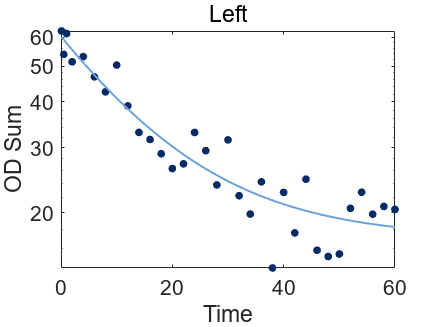


saveas(f_left,[maindir,'Abs-',num2str(last),'\fLeft.fig'])
saveas(f_left,[maindir,'Abs-',num2str(last),'\fLeft.png'])


% Save results %

clear main_dir_0
save([maindir,'Abs-',num2str(last),'\result.mat'])

clear Timelist


function [fitresult] = createFit(xaxis, ODsum1)
%CREATEFIT(XAXIS,ODSUM1)
%  创建一个拟合。
%
%  要进行 '无标题拟合 1' 拟合的数据:
%      X 输入: xaxis
%      Y 输出: ODsum1
%  输出:
%      fitresult: 表示拟合的拟合对象。
%      gof: 带有拟合优度信息的结构体。
%
%  另请参阅 FIT, CFIT, SFIT.

%  由 MATLAB 于 04-Sep-2023 17:31:02 自动生成


%% 拟合: '无标题拟合 1'。
[xData, yData] = prepareCurveData( xaxis, ODsum1 );

% 设置 fittype 和选项。
ft = fittype( 'a*exp(-x/t1)+a2*exp(-x/t2)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [10 5 100 50];

% 对数据进行模型拟合。
[fitresult, gof] = fit( xData, yData, ft, opts );


end

%%
